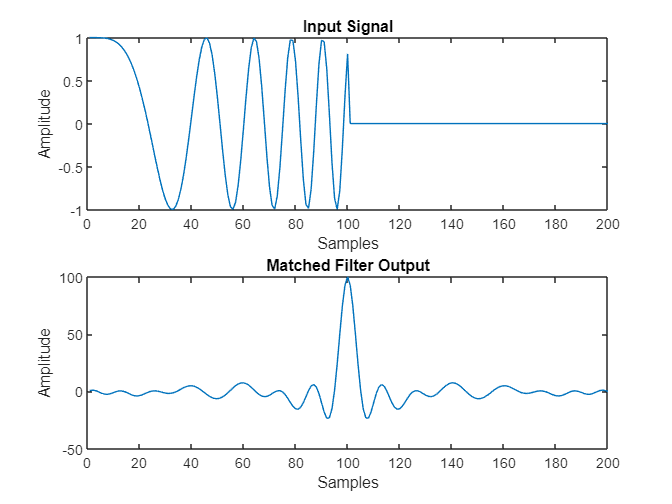

waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3);
x = waveform();
filter = phased.MatchedFilter( ...
    'Coefficients',getMatchedFilter(waveform));
y = filter(x);
subplot(2,1,1),plot(real(x))
xlabel('Samples')
ylabel('Amplitude')
title('Input Signal')
subplot(2,1,2),plot(real(y))
xlabel('Samples')
ylabel('Amplitude')
title('Matched Filter Output')

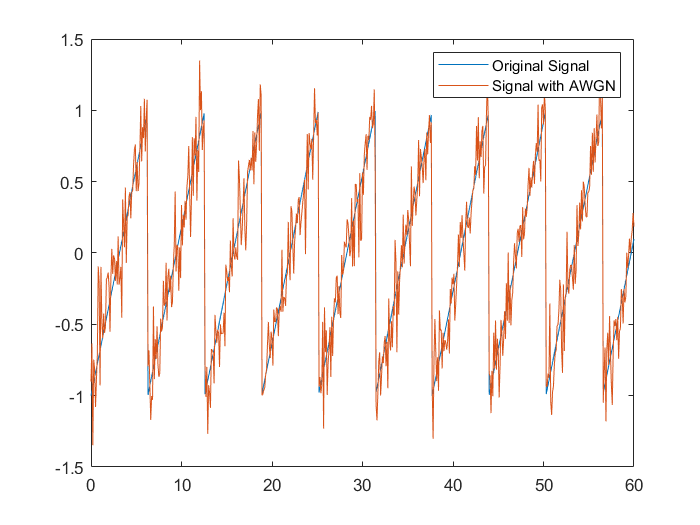

t = (0:0.1:60)';
x = sawtooth(t);
y = awgn(x,10,'measured');
plot(t,[x y])
legend('Original Signal','Signal with AWGN')

filter = phased.MatchedFilter();

Unable to resolve the name phased.MatchedFilter.

y_saw = filter(y);
subplot(2,1,1),plot(real(y))
xlabel('Samples')
ylabel('Amplitude')
title('Input Signal')
subplot(2,1,2),plot(real(y_saw))
xlabel('Samples')
ylabel('Amplitude')
title('Matched Filter Output')

x = square(t);
y = awgn(x,10,'measured');
plot(t,[x y])
legend('Original Signal','Signal with AWGN')
filter = phased.MatchedFilter();
y_saw = filter(y);
subplot(2,1,1),plot(real(y))
xlabel('Samples')
ylabel('Amplitude')
title('Input Signal')
subplot(2,1,2),plot(real(y_saw))
xlabel('Samples')
ylabel('Amplitude')
title('Matched Filter Output')

waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
    'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
    'SweepBandwidth',1e5);
wav = getMatchedFilter(waveform);
filter = phased.MatchedFilter('Coefficients',wav);
taylorfilter = phased.MatchedFilter('Coefficients',wav,...
    'SpectrumWindow','Taylor');
sig = waveform();
rng(17)
x = sig + 0.5*(randn(length(sig),1) + 1j*randn(length(sig),1));
y = filter(x);
y_taylor = taylorfilter(x);

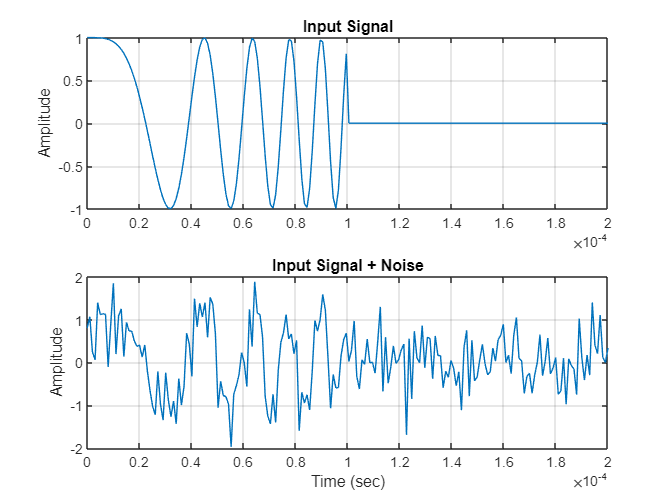

t = linspace(0,numel(sig)/waveform.SampleRate,...
    waveform.SampleRate/waveform.PRF);
subplot(2,1,1)
plot(t,real(sig))
title('Input Signal')
xlim([0 max(t)])
grid on
ylabel('Amplitude')
subplot(2,1,2)
plot(t,real(x))
title('Input Signal + Noise')
xlim([0 max(t)])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')

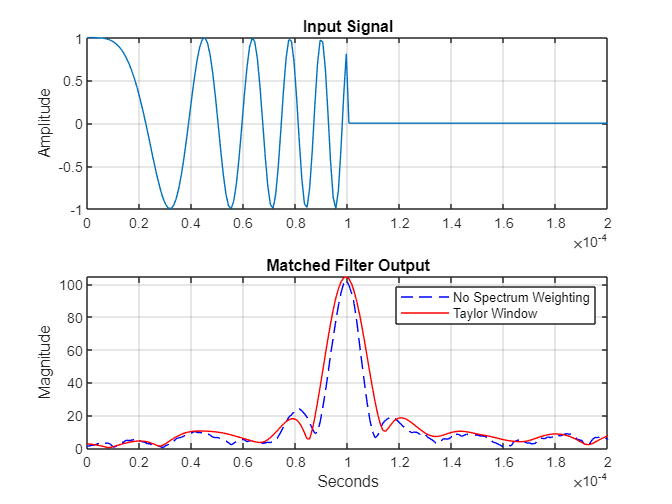

plot(t,abs(y),'b--')
title('Matched Filter Output')
xlim([0 max(t)])
grid on
hold on
plot(t,abs(y_taylor),'r-')
ylabel('Magnitude')
xlabel('Seconds')
legend('No Spectrum Weighting','Taylor Window')
hold off

antenna = phased.IsotropicAntennaElement('FrequencyRange',[5e9 15e9]);
transmitter = phased.Transmitter('Gain',20,'InUseOutputPort',true);
fc = 10e9;
target = phased.RadarTarget('Model','Nonfluctuating',...
   'MeanRCS',1,'OperatingFrequency',fc);
txloc = [0;0;0];
tgtloc = [5000;5000;10];
transmitterplatform = phased.Platform('InitialPosition',txloc);
targetplatform = phased.Platform('InitialPosition',tgtloc);
[tgtrng,tgtang] = rangeangle(targetplatform.InitialPosition,...
   transmitterplatform.InitialPosition);
waveform = phased.RectangularWaveform('PulseWidth',25e-6,...
   'OutputFormat','Pulses','PRF',10e3,'NumPulses',1);
c = physconst('LightSpeed');
maxrange = c/(2*waveform.PRF);
SNR = npwgnthresh(1e-6,1,'noncoherent');

lambda = physconst('LightSpeed')/target.OperatingFrequency;
Ts = 290;
dbterms = db2pow(SNR - 2*transmitter.Gain);
Pt = (4*pi)^3*physconst('Boltzmann')*Ts/waveform.PulseWidth/target.MeanRCS/(lambda^2)*maxrange^4*dbterms;
transmitter.PeakPower = Pt;

radiator = phased.Radiator('PropagationSpeed',c,...
   'OperatingFrequency',fc,'Sensor',antenna);
channel = phased.FreeSpace('PropagationSpeed',c,...
   'OperatingFrequency',fc,'TwoWayPropagation',false);
collector = phased.Collector('PropagationSpeed',c,...
   'OperatingFrequency',fc,'Sensor',antenna);
receiver = phased.ReceiverPreamp('NoiseFigure',0,...
   'EnableInputPort',true,'SeedSource','Property','Seed',2e3);
filter = phased.MatchedFilter(...
   'Coefficients',getMatchedFilter(waveform),...
   'GainOutputPort',true);

wf = waveform();
[wf,txstatus] = transmitter(wf);
wf = radiator(wf,tgtang);
wf = channel(wf,txloc,tgtloc,[0;0;0],[0;0;0]);
wf = target(wf);
wf = channel(wf,tgtloc,txloc,[0;0;0],[0;0;0]);
wf = collector(wf,tgtang);
rx_puls = receiver(wf,~txstatus);
[mf_puls,mfgain] = filter(rx_puls);
Gd = length(filter.Coefficients)-1;

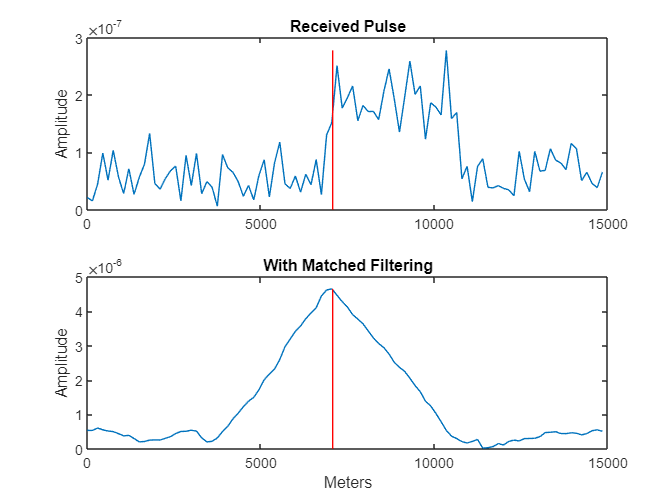

mf_puls=[mf_puls(Gd+1:end); mf_puls(1:Gd)];
subplot(2,1,1)
t = unigrid(0,1e-6,1e-4,'[)');
rangegates = c.*t;
rangegates = rangegates/2;
plot(rangegates,abs(rx_puls))
title('Received Pulse')
ylabel('Amplitude')
hold on
plot([tgtrng, tgtrng], [0 max(abs(rx_puls))],'r')
subplot(2,1,2)
plot(rangegates,abs(mf_puls))
title('With Matched Filtering')
xlabel('Meters')
ylabel('Amplitude')
hold on
plot([tgtrng, tgtrng], [0 max(abs(mf_puls))],'r')
hold off